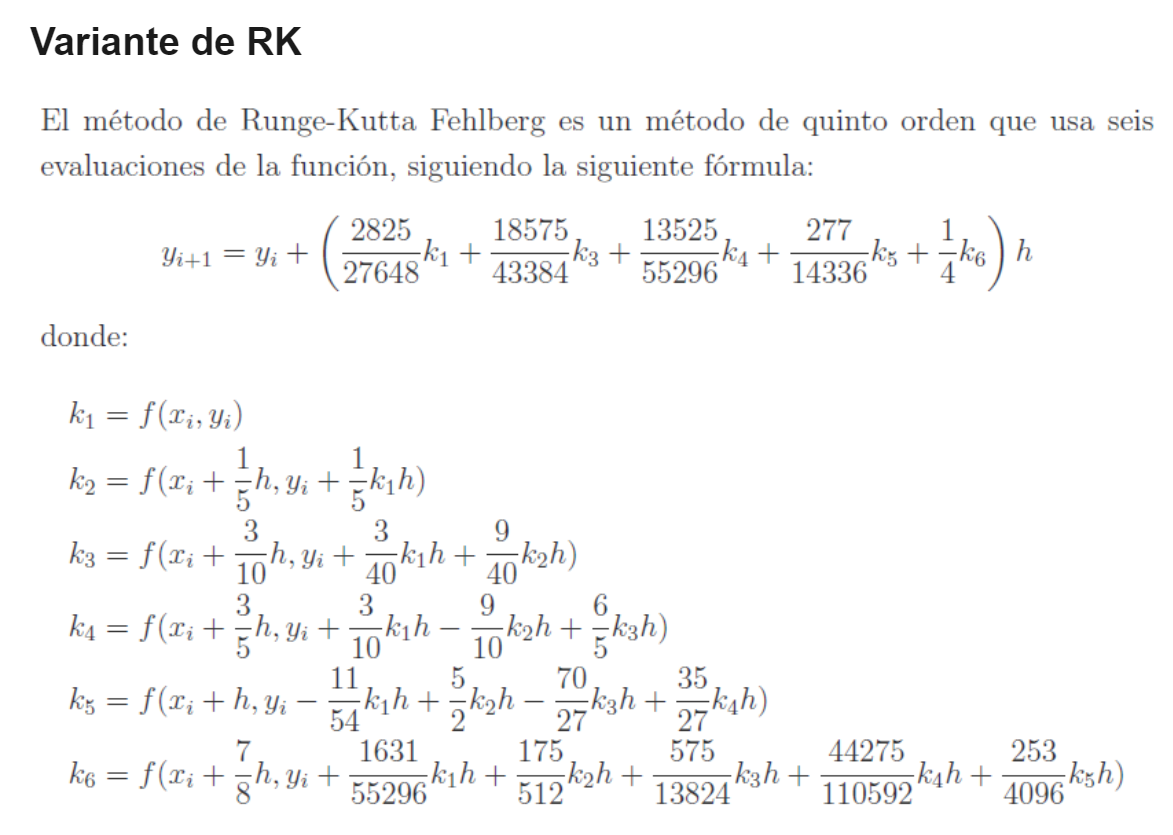

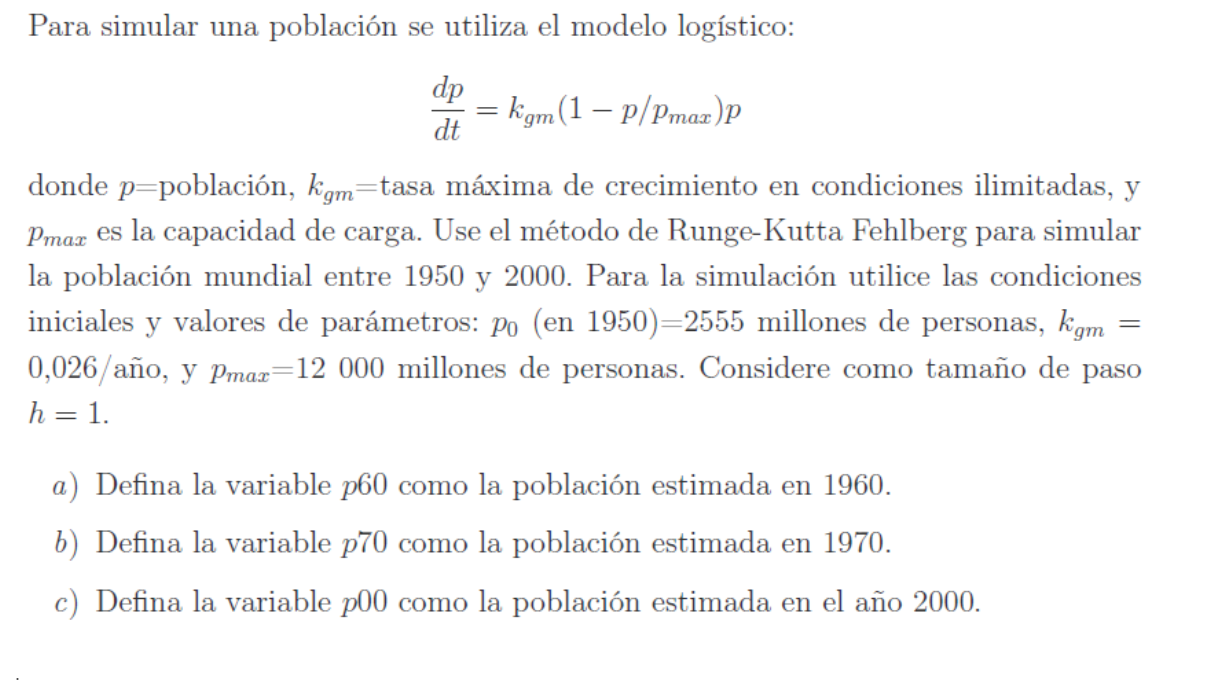

%primer item
a=1950;b=1960;y0=2555;kgm = 0.026;pmax = 12000;h = 1;% definicion de condiciones iniciales 
f = @(t,y)(kgm*y*(1-y/pmax));
z1 = rk5(f,a,b,y0,h);
p60 = z1(end) 

p60 =      3.142972281612404e+03



%sedundo item
b=1970;
f = @(t,y)(kgm*y*(1-y/pmax));
z2 = rk5(f,a,b,y0,h);
p70 = z2(end) 

p70 =      3.811705651158352e+03



%tercer item
b=2000;
f = @(t,y)(kgm*y*(1-y/pmax));
z3 = rk5(f,a,b,y0,h);
p00 = z3(end) 

p00 =      6.149281664189330e+03


function z = rk5(f,a,b,y0,h)
    xx = a:h:b; xx = xx';
    y1(1,1) = y0;
    for i=1:length(xx)-1
    k1 = f(xx(i),y0);
    k2 = f(xx(i) + h/5,y0 + k1*(h/5));
    k3 = f(xx(i) + h*(3/10),y0 + (3/40)*k1*h + (9/40)*k2*h);
    k4 = f(xx(i)+ h*(3/5),y0 + (3/10)*k1*h - (9/10)*k2*h + (6/5)*k3*h);
    k5 = f(xx(i)+ h,y0 - (11/54)*k1*h + (5/2)*k2*h - (70/27)*k3*h + (35/27)*k4*h);
    k6 = f(xx(i)+ (7/8)*h,y0 + (1631/55296)*k1*h + (175/512)*k2*h + (575/13824)*k3*h + (44275/110592)*k4*h + (253/4096)*k5*h);    
    y1(i+1,1) = y0 + ((2825/27648)*k1 + (18575/43384)*k3 + (13525/55296)*k4 + (277/14336)*k5 + (1/4)*k6)*h;
    y0 = y1(i+1,1);
    end
    z = y1;
end